## Lab1 

### Task 1

Generate three periods of a continuous-time sinusoid with amplitude A = 2, fre-

quency f = 3 Hz (ω = 2πf), and phase φ = π/3. In addition, create a second sinu-

soid of equal length (in time). The second sinusoid should have amplitude A = 2,

frequency f = 1 Hz, and phase φ = 0. Plot these in the same figure, one of the

signals should be dashed while the other should be solid, see `help plot`, and `help`

`hold`. Remember to choose the time vector t, so that the figures look good

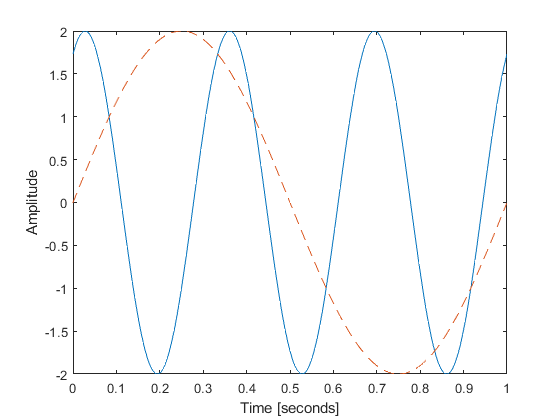

task1 = figure('Name','Task 1');
figure(task1)
sinusoid = @(A,Omega,phase,t) A*sin(Omega.*t+phase);
sin1_A = 2; % Amplitude
sin2_A = 2; % Amplitude
sin1_f = 3; % In hz
sin2_f = 1; % In hz
sin1_p = pi./3; % Phase in radians
sin2_p = 0; % Phase in radians
sin1 = @(t) sinusoid(sin1_A,sin1_f.*2.*pi,sin1_p,t);
sin2 = @(t) sinusoid(sin2_A,sin2_f.*2.*pi,sin2_p,t);
time_range = [0,3*1/sin1_f];
fplot(sin1,time_range);
hold on
fp = fplot(sin2,time_range);
fp.LineStyle = '--';
xlabel("Time [seconds]")
ylabel("Amplitude")
hold off

### Task 2

Generate the following three continuous-time signals for the time interval −1 ≤t ≤2

• x(t) = cos(6πt)

• y(t) = |t|^`1/3`

• z(t) = x(t)y(t)

Plot the three signals in the same window, but in three different figures, see `subplot`

task2 = figure('Name',"Task 2");
figure(task2);
x = @(t) cos(6.*pi.*t);
y = @(t) abs(t).^(1/3);
z = @(t) x(t).*y(t);
t = [-1,2]

t =     -1     2


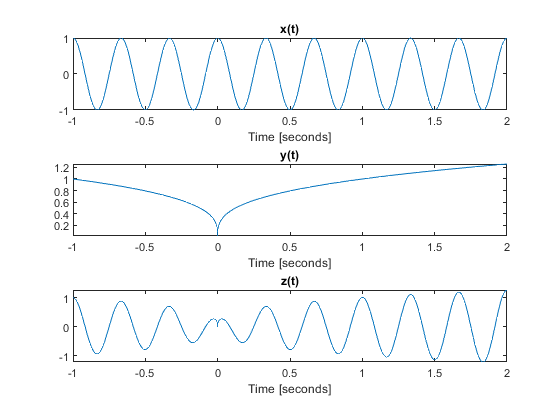

title("Task 2");
subplot(3,1,1);
fplot(x,t);
title("x(t)");
xlabel("Time [seconds]");
subplot(3,1,2);
fplot(y,t);
title("y(t)");
xlabel("Time [seconds]");
subplot(3,1,3);
fplot(z,t);
title("z(t)");
xlabel("Time [seconds]");

### Task 3

Repeat Exercise 2 for the three discrete-time signals obtained by sampling x(t), y(t),

and z(t) using Ts = 1/5 s, i.e., illustrate

• x[n] = x(nTs)

• y[n] = y(nTs)

• z[n] = z(nTs)

Remember to label the axes carefully

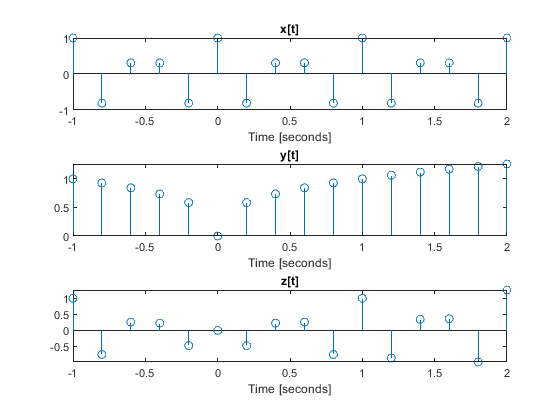

task3 = figure("Name","Task 3");

times = -1:1./5:2;
disc_x = x(times);
disc_y = y(times);
disc_z = z(times);
subplot(3,1,1);
stem(times,disc_x);
xlabel("Time [seconds]");
title("x[t]");
subplot(3,1,2);
stem(times,disc_y);
xlabel("Time [seconds]");
title("y[t]");
subplot(3,1,3);
stem(times,disc_z);
xlabel("Time [seconds]");
title("z[t]");

### Task 4

A particular LTI system, call it System 1, is described through the input-output

relation

y[n] =1/8( x[n] + x[n −1] + x[n −2] + x[n −3] + x[n −4] + x[n −5] + x[n −6] + x[n −7])

Find the impulse response, h1[n], of System 1 (analytically).

Simple, 


$$Y\left\lbrack n\right\rbrack =h\left\lbrack n\right\rbrack *x\left\lbrack n\right\rbrack \Rightarrow h\left\lbrack n\right\rbrack =\frac{1}{8}\left(\delta \left\lbrack n\right\rbrack +\delta \left\lbrack n-1\right\rbrack +\delta \left\lbrack n-2\right\rbrack +\delta \left\lbrack n-3\right\rbrack +\delta \left\lbrack n-4\right\rbrack +\delta \left\lbrack n-5\right\rbrack +\delta \left\lbrack n-6\right\rbrack +\delta \left\lbrack n-7\right\rbrack \right)$$


And expressed in code it is

unit_sig = @(start_p,end_p,delay) start_p:1:end_p == delay;
step_sig = @(start_p,end_p,plat_start,plat_end) (start_p:1:end_p <= plat_end) - (start_p:1:end_p < plat_start);
convolve = @(x,h,n,k_start,k_end) h(k_start:1:k_end).*(x(n-(k_end-k_start):1:n));


differential_signal = (1./8)*ones([1,8]);
h = (1./8)*ones([1,8]);
h_handle = @(n) (n<=7 & n>= 0).*(1./8);






### Task 5

Use Matlab to find the output obtained by feeding the input signal

x[n] =.5^n

for 0 ≤n ≤10

0 otherwise

through System 1. Illustrate the input and output signals in an appropriate way.

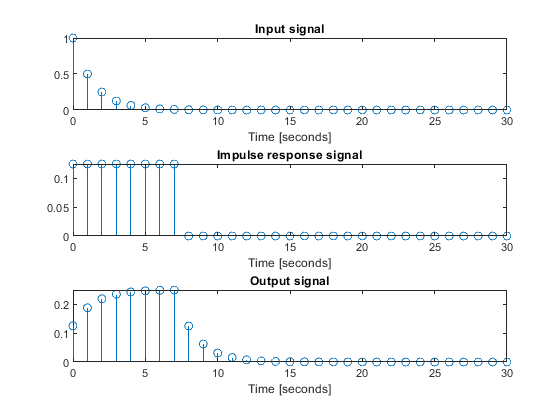

time_steps = 30;
unit_resp = h;
unit_resp(time_steps+1) = 0;
time = 0:1:time_steps;
task5 = figure("Name","task 5");

sig_in = @(x) (x <= 10 ).*( x >= 0).*(0.5.^x);
transfer = @(n,k_start,k_end,sig_in,h) sum(convolve(sig_in,h,n,k_start,k_end));
out = time;
for i = out
    out(i+1) = transfer(i,1,length(h),sig_in,h);
end

% Plot things
figure(task5);
subplot(3,1,1);
stem(time,sig_in(time));
xlabel("Time [seconds]");
title("Input signal");
subplot(3,1,2);
stem(time,unit_resp);
xlabel("Time [seconds]");
title("Impulse response signal");
subplot(3,1,3);
stem(time,out);
xlabel("Time [seconds]");
title("Output signal");

### Task 6

Repeat Exercise 5, but this time by using the input signal x2[n] = x[n + 2].

time = 0:1:time_steps;
sig_in_2 = @(n)sig_in(n+2)

sig_in_2 = function_handle with value:
    @(n)sig_in(n+2)


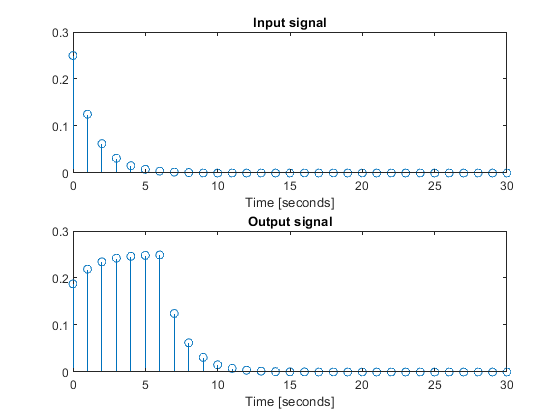

out = time;
for i = out
    out(i+1) = transfer(i,0,length(h),sig_in_2,h_handle);
end

task6 = figure("Name","task 6");


% Plot things
figure(task6);
subplot(2,1,1);
stem(time,sig_in_2(time));
xlabel("Time [seconds]");
title("Input signal");
subplot(2,1,2);
stem(time,out);
xlabel("Time [seconds]");
title("Output signal");

### Task 7

Repeat Exercise 5, but this time consider a system with impulse response

h2[n] = h1[−n]

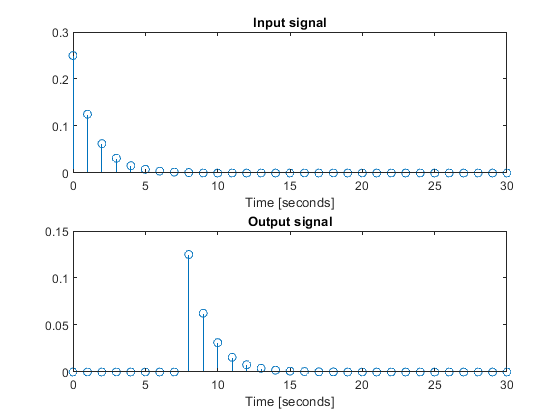

% Might just output straight 0 since the input is never n < 0
h2_handle = @(n) h_handle(-n);
time = 0:1:time_steps;
out = time;
for i = out
    out(i+1) = transfer(i,0,length(h),sig_in,h2_handle);
end

task7 = figure("Name","task 6");


% Plot things
figure(task7);
subplot(2,1,1);
stem(time,sig_in_2(time));
xlabel("Time [seconds]");
title("Input signal");
subplot(2,1,2);
stem(time,out);
xlabel("Time [seconds]");
title("Output signal");

## Task 8

Repeat Exercise 5 but this time by using the input signal

x[n] = cos (π/8 n) + cos( π/4 n) for 0 ≤n ≤127

0 otherwise

Comment on the results, especially regarding the frequency content of the input and

output signals. Can you explain this behavior?

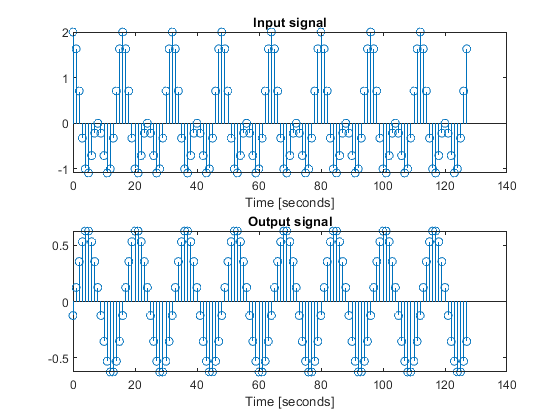

time_steps = 127;
time = 0:1:time_steps;
sig = @(n)cos((pi/8).*n) + cos((pi/4).*n);
out = time;
for i = out
    out(i+1) = transfer(i,0,length(h),sig,h_handle);
end


task8 = figure("Name","task 8");


% Plot things
figure(task8);
subplot(2,1,1);
stem(time,sig(time));
xlabel("Time [seconds]");
title("Input signal");
subplot(2,1,2);
stem(time,out);
xlabel("Time [seconds]");
title("Output signal");

### Task 9

In the file `eva.mat`, two Matlab variables `xl` and `xr` can be found. You can load these

into the workspace through the load command, see `help load`. `xl` and `xr` contains

the left and right channel of an audio segment sampled at 44,1 kHz. You can listen

to it in Matlab using the `sound` command,

`sound([xl,xr],44100)`

Feed both channels through System 1 and listen to the result. Comment briefly

on how you experience the processed audio signal.

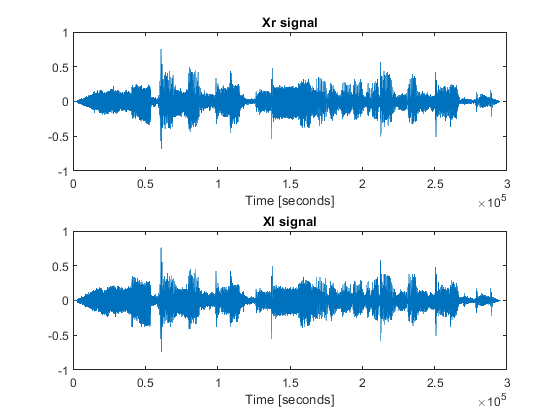


data = load("eva.mat",'xr','xl');
xr = data.xr;
xl = data.xl;
out_xr = 1:length(xr);
out_xl = 1:length(xr);
for n = out_xr

    
    for k = 1:length(h)
        if n-k >0
            out_xr(n) = h(k).*xr(n-k);
            out_xl(n) = h(k).*xl(n-k);
        end
        
    end
end
% Plot original signal
task9 = figure("Name","task 9");
figure(task9);
subplot(2,1,1);
plot(1:length(xr),xr);
xlabel("Time [seconds]");
title("Xr signal");
subplot(2,1,2);
plot(1:length(xr),xl);
xlabel("Time [seconds]");
title("Xl signal");

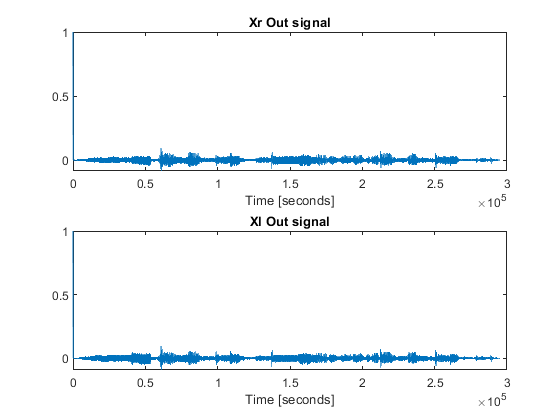


task9_2 = figure("Name","task 9 2");

figure(task9_2);
subplot(2,1,1);
plot(1:length(xr),out_xr);
xlabel("Time [seconds]");
title("Xr Out signal");
subplot(2,1,2);
plot(1:length(xr),out_xl);
xlabel("Time [seconds]");
title("Xl Out signal");

%sound([xl,xr],44100);
%sound([out_xl,out_xr],44100);

The processed audio seems more quiet, it should also be less noisy since it the filter is a rolling sum.